# Solving nonlinear equations

This script demonstrates how nonlinear equations (systems) can be solved in Matlab. It is demonstrated by the nonlinear Pacejka tire model (magic formula).  

## Pacejka tire model (Magic formula)

The traction force of a tire can be computed based on the gravity force between the ground and tire as:

$F_t = \mu (\nu) \cdot F_g$,

where $\mu (\nu)$ is the so-called normalized force depending on the $\nu$ tire slip. The definition of the tire slip is:


$$\nu = \begin{cases} 
\frac{u - R\omega}{u} \quad \mathrm{if\ } u > R\omega \\
\frac{R\omega - u}{R\omega} \quad \mathrm{if\ } R\omega > u
\end{cases}$$


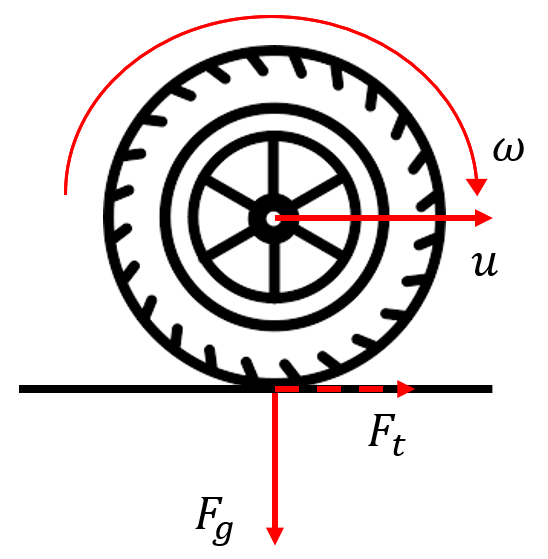

The Pacejka slip model describes the normalized force applied on the tire depending on the slip based on the following nonlinear function:

 $\mu = D \cdot \sin\left(C \arctan \left( B \cdot \nu - E \cdot \left( B\cdot\nu - \arctan(B\cdot\nu) \right) \right) \right) $,

where $B,C,D,E$ are model parameters depending on the tire and the ground conditions.

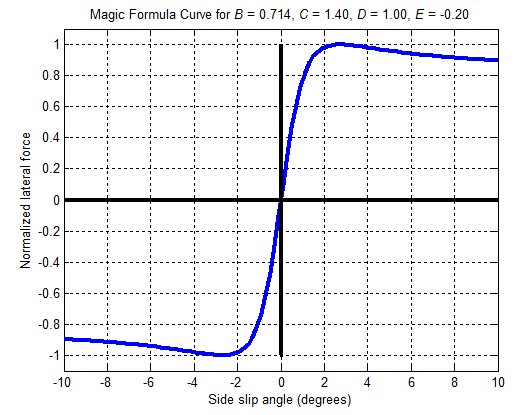

## Creating Pacejka tire model

Creating function handle of generic Pacejka model based on pre-implemented magic formula:

magicFormulaFcnHandle = @(slip, paramStruct) magicFormula(slip, paramStruct);

### Model parameter definition

#### Maximal friction coefficient (D) 

modelParams.maxFrictionCoeff = 1.0;

#### Shape factor (C)  

modelParams.shapeFactor = 1.45;

#### Stiffness factor (B)

modelParams.stiffnessFactor = 15.0;

#### Curvature factor (E)

modelParams.curvatureFactor = 0.4;

Creating function handle of the current tire model with given params:

tireModelFcnHandle = @(slip) magicFormulaFcnHandle(slip, modelParams);

## Compute the normalized force values (Values of Pacejka slip curve)

Creating discrete slip values:

slipVector = -1 : 0.01 : 1;

Computing the normalized force values by evaluating the function handle for the given slip values: 

normalizedForceValues = tireModelFcnHandle(slipVector);

## Solving the nonlinear equation

We are looking for the $\nu_{90}$ slip value, where $\mu(\nu_{90}) = \mu_{90} = 0.9 \cdot \mu_{max}$. To obtain the $\nu_{90}$ the specific slip value the following nonlinear equation must be solved:


$$\mu(\nu_{90}) - 0.9 \cdot \mu_{max} = 0$$


mu90 = 0.9 * modelParams.maxFrictionCoeff;

The function handle whose root we are looking for:

fcnHandleSlip90 = @(nu) tireModelFcnHandle(nu) - mu90;

Start the numerical solution from $\nu = 0$

[nu90_0, F90_0] = fsolve(fcnHandleSlip90, 0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Start the numerical solution from $\nu = 1$

[nu90_1, F90_1] = fsolve(fcnHandleSlip90, 1);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


The results:

fprintf('mu(%g)=%g (from initial point s=%g)\n', nu90_0, mu90 + F90_0, 0);

mu(0.0717041)=0.9 (from initial point s=0)


fprintf('mu(%g)=%g (from initial point s=%g)\n', nu90_1, mu90 + F90_1, 1);

mu(0.558672)=0.9 (from initial point s=1)


## Plotting the results

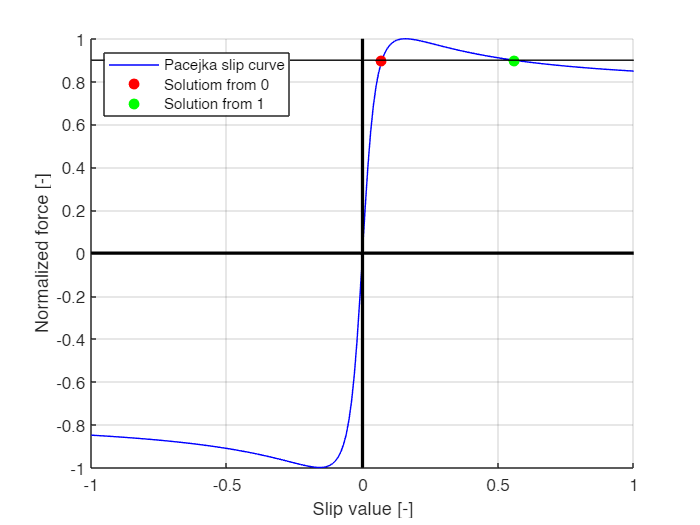

fig = figure('Name', 'Pacejka slip curve', 'Color', 'White');
ax = axes(fig);
hold(ax, 'on');
grid(ax, 'on');
plot(ax, slipVector, normalizedForceValues, 'b-');
plot(ax, nu90_0, mu90 + F90_0, 'o', 'MarkerFaceColor', 'red', 'MarkerEdgeColor', 'red');
plot(ax, nu90_1, mu90 + F90_1, 'o', 'MarkerFaceColor', 'green', 'MarkerEdgeColor', 'green');
plot(ax, [-1; 1], [mu90; mu90], 'Color', 'black');
plot(ax, [-1; 1], [0; 0], 'Color', 'black', 'LineWidth', 2);
plot(ax, [0; 0], [-1; 1], 'Color', 'black', 'LineWidth', 2);
legend(ax, {'Pacejka slip curve', 'Solutiom from 0', 'Solution from 1'}, 'Location', "northwest");
xlabel('Slip value [-]');
ylabel('Normalized force [-]');